# E16 - Opgave 5 Powerspektrum

Opgave a:

a = [-0.4 2.9 4.2 1.3 -1.2 -5.9 -2.7 5.9 1.0 -1.9 ...
    -1.7 -1.4 -0.1 3.9 4.4 1.1 -3.3 -6.4 -2.5 6.2 ...
    6.5 2.0 0.5 -1.4 0.5 2.3 2.9 -1.1 -5.2 -5.7 ...
    -3.4 5.4 6.3 0.8 0.3 -0.9 0.5 3.8 2.4 -1.8 ...
    -4.2 -6.3 0.9 5.6 2.3 -1.3 -1.0 -1.5 0.6 3.5 ...
    0.3 3.8 -3.1 -7.3 2.8 -3.8 -5.7 -0.7 -2.3 -1.2 ...
    1.6 3.1 1.2 2.5 -3.4 -5.5 1.5 0.3 -3.3 -2.0 ...
    -1.2 -0.8 1.4 2.8 2.2 1.2 -5.9 -4.6 6.1 1.1 ...
    -0.7 -1.0 -2.0 -0.6 2.5 4.8 2.1 -3.1 -5.6 -4.9 ...
    2.9 5.1 2.7 1.3 -1.3 0.4 2.8 2.1 -0.0 -5.3]; % 100 målinger

h = 0.1;
tid = 100 *h;

t = linspace(0,9.9,100);

plot(t,a)
xlabel("Tiden i sekunder")
ylabel("Accelerationsmåler")

Opgave b:

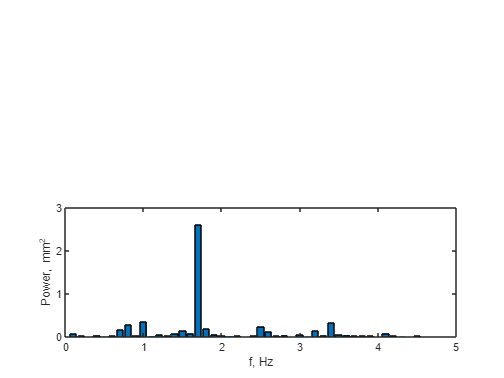

y = a;                      % Vores datasæt
%% -------------------------------------------------
dt = 0.1;                   % Samplingsinterval (s)
n = length(y);              % Antal samplinger
T = n*dt;                   % Signallængde (s)
t = (0:n-1)*dt;             % Tidsvektor (s)
Y = fft(y)/n;               % FFT af y (mm)
fs = 1/dt;                  % Samplingsfrekvens (Hz)
fmax = fs/2;                % Maks frekvens (Hz)
df = 1/T;                   % Frekvensstep (Hz)
f = (0:n-1)*df;             % Frekvensvektor (Hz)
P = real(Y).^2 + imag(Y).^2;% Powervektor
subplot(2,1,2)
bar(f,P);                   % Plot af powerspektrum
xlim([0 fmax]);             % Afgræns frekvensakse
xlabel('f, Hz'), ylabel('Power, mm^2')

res = find(P==max(P))       % Finder både real og en imagenær powervektor

res =     18    84


Frek = f(res(1))             % Bestemmer frekvensen for den første af de to fundne peaks.

Frek = 1.7000


% Hvis en person går 10000 skridt med en frekvens på 1.7 Hz
skridt_tid_i_sek = 10000/Frek

skridt_tid = 5.8824e+03

# E17 FEM

%% 1.A)
L = [605 552 494 552 605]*1e-3;
A = [390 293 185 293 390]*1e-6;
E = [210 210 210 210 210]*1e+9;
F = 4401;

NL = length(L); 
NA = length(A); 
NE = length(E);

if NL ~= NA || NL ~= NE
 error('L, A and E vectors must be same length');
end
n = length(L);
k = A.*E./L;
% Build overall stiffness matrix K
K = zeros(n+1,n+1);
for i = 1:n
 Kelem = [k(i)  -k(i); -k(i) k(i)]; % Stiffness mat. for elem. i
 K(i:i+1,i:i+1) = K(i:i+1,i:i+1) + Kelem; % Add stiffn. mat. for elem. i
end
% System of equations - construct matrix and vector and solve
%% 1.B)
Kred = K(2:5,2:5)

Kred = 1.0e+08 *

    2.4684   -1.1147         0         0
   -1.1147    1.9011   -0.7864         0
         0   -0.7864    1.9011   -1.1147
         0         0   -1.1147    2.4684


Fvec = [0 0 F 0]

Fvec =            0           0        4401           0


D = inv(Kred).*Fvec

D = 1.0e-04 *

         0         0    0.1171         0
         0         0    0.2592         0
         0         0    0.4607         0
         0         0    0.2080         0


# E17 Første orden - Euler & Runge

%% 2.A)
t = linspace(0,560,15);
arr = [];
arr1 = [];
arr2 = [];
h = 40;
Rb = 0.5;
r_u = 0.01;
g = 9.81;
y_o = 0.8;

for i=t
    if i == 0;
        y = y_o;
        arr(end+1) = y;
        dydt = r_u^2 * ((sqrt(2*g*y))/((y-2*Rb)*y));
        arr1(end+1) = dydt;
    else i>0;
        yold = y;
        ynew = yold + dydt*h;
        arr(end+1) = ynew;
        dydt = r_u^2 * ((sqrt(2*g*ynew))/((ynew-2*Rb)*ynew));
        arr1(end+1) = dydt;
        y = ynew;
    end
end
varNames = {'t', 'y', 'dydt'};
rootTable = table(t',arr', arr1','VariableNames',varNames)

rootTable = 15×3 table
     t         y           dydt   
    ___    _________    __________

      0          0.8    -0.0024761
     40      0.70095    -0.0017692
     80      0.63019    -0.0015088
    120      0.56984    -0.0013641
    160      0.51527     -0.001273
    200      0.46435    -0.0012135
    240      0.41581    -0.0011758
    280      0.36878    -0.0011555
    320      0.32256    -0.0011513
    360      0.27651    -0.0011643
    400      0.22993    -0.0011996
    440      0.18195    -0.0012694
    480      0.13118    -0.0014076
    520     0.074871    -0.0017498
    560    0.0048788    -0.0063726



display("Ved 360 sek er vandhøjden 0.2765 meter")

    "Ved 360 sek er vandhøjden 0.2765 meter"




%% 2.B)
clear

%variabler:
Rb = 0.5;
r_u = 0.01;
g = 9.81;
y_o = 0.8;

dydt =@(t,y) r_u^2 * ((sqrt(2*g*y))/((y-2*Rb)*y));

h = 40;
t(1) = 0;
y(1) = y_o;
for j = 1:(560/h)
 t(j+1) = t(j) + h;
 k1 = dydt(t(j),y(j));
 tmid1 = t(j) + h/2;
 Ymid1 = y(j) + k1*h/2;
 k2 = dydt(tmid1,Ymid1);
 tmid2 = t(j) + h/2;
 Ymid2 = y(j) + k2*h/2;
 k3 = dydt(tmid2,Ymid2);
 tend = t(j) + h;
 Yend = y(j) + k3*h;
 k4 = dydt(tend,Yend);
 phi = (k1 + 2*k2 + 2*k3 + k4)/6;
 y(j+1) = y(j) + phi*h;
end

varNames = {'t', 'y'};
rootTable = table(t',y','VariableNames',varNames)

rootTable = 15×2 table
     t         y    
    ___    _________

      0          0.8
     40      0.71577
     80      0.64823
    120      0.58912
    160      0.53512
    200      0.48447
    240      0.43606
    280      0.38908
    320      0.34286
    360      0.29677
    400       0.2501
    440      0.20189
    480      0.15058
    520       0.0925
    560    0.0020995
